setenv("RMW_IMPLEMENTATION", "rmw_fastrtps_cpp")
getenv("RMW_IMPLEMENTATION")

ans = 'rmw_fastrtps_cpp'


setenv('ROS_DOMAIN_ID','0')
getenv('ROS_DOMAIN_ID')

ans = '0'


test1 = ros2node('/test1');
test2 = ros2node('/test2');

ros2 node list

/camera_pkg/camera_node
/ctrl_pkg/ctrl_node
/deepracer_navigation_pkg/deepracer_navigation_node
/deepracer_systems_pkg/deepracer_systems_scripts_node
/deepracer_systems_pkg/model_loader_node
/deepracer_systems_pkg/network_monitor_node
/deepracer_systems_pkg/otg_control_node
/deepracer_systems_pkg/software_update_node
/device_info_pkg/device_info_node
/i2c_pkg/battery_node
/inference_pkg/inference_node
/model_optimizer_pkg/model_optimizer_node
/rplidar_ros/rplidarNode
/sensor_fusion_pkg/sensor_fusion_node
/servo_pkg/servo_node
/status_led_pkg/status_led_node
/test1
/test2
/usb_monitor_pkg/usb_monitor_node
/web_video_server/web_video_server
/web_video_server/web_video_server
/webserver_pkg/webserver_publisher_node



ros2 topic list -t

                           Topic                                                   MessageType                       
    ____________________________________________________    _________________________________________________________

    {'/camera_pkg/display_mjpeg'                       }    {'sensor_msgs/Image'                                    }
    {'/camera_pkg/video_mjpeg'                         }    {'deepracer_interfaces_pkg/CameraMsg'                   }
    {'/ctrl_pkg/raw_pwm'                               }    {'deepracer_interfaces_pkg/ServoCtrlMsg'                }
    {'/ctrl_pkg/servo_msg'                             }    {'deepracer_interfaces_pkg/ServoCtrlMsg'                }
    {'/deepracer_navigation_pkg/auto_drive'            }    {'deepracer_interfaces_pkg/ServoCtrlMsg'                }
    {'/deepracer_systems_pkg/network_connection_status'}    {'deepracer_interfaces_pkg/NetworkConnectionStatus'     }
    {'/deepracer_systems_pkg/software_update_pct'      


ros2 msg list

action_msgs/CancelGoalRequest
action_msgs/CancelGoalResponse
action_msgs/GoalInfo
action_msgs/GoalStatus
action_msgs/GoalStatusArray
actionlib_msgs/GoalID
actionlib_msgs/GoalStatus
actionlib_msgs/GoalStatusArray
builtin_interfaces/Duration
builtin_interfaces/Time
composition_interfaces/ListNodesRequest
composition_interfaces/ListNodesResponse
composition_interfaces/LoadNodeRequest
composition_interfaces/LoadNodeResponse
composition_interfaces/UnloadNodeRequest
composition_interfaces/UnloadNodeResponse
diagnostic_msgs/AddDiagnosticsRequest
diagnostic_msgs/AddDiagnosticsResponse
diagnostic_msgs/DiagnosticArray
diagnostic_msgs/DiagnosticStatus
diagnostic_msgs/KeyValue
diagnostic_msgs/SelfTestRequest
diagnostic_msgs/SelfTestResponse
example_interfaces/AddTwoIntsRequest
example_interfaces/AddTwoIntsResponse
example_interfaces/Bool
example_interfaces/Byte
example_interfaces/ByteMultiArray
example_interfaces/Char
example_interfaces/Empty
example_interfaces/Float32
example_interfaces/Float32Mu

ridarSub = ros2subscriber(test1, "/rplidar_ros/scan");
tic
figure
i=1;
scans = struct([]);

while toc < 330
    ridarData = receive(ridarSub,1);
    scan = rosReadLidarScan(ridarData);
    scans{i} = scan;
    rosPlot(ridarData)
    i = i+1;
end

sub = ros2subscriber(test2, "/sensor_fusion_pkg/overlay_msg")

sub =   ros2subscriber - 속성 있음:

        TopicName: '/sensor_fusion_pkg/overlay_msg'
    LatestMessage: []
      MessageType: 'sensor_msgs/Image'
    NewMessageFcn: []
          History: 'keeplast'
            Depth: 10
      Reliability: 'reliable'
       Durability: 'volatile'



[scanData1,status1,statustext1] = receive(sub,5)

scanData1 = 다음 필드를 포함한 struct :
     MessageType: 'sensor_msgs/Image'
          header: [1×1 struct]
          height: 120
           width: 160
        encoding: 'bgr8'
    is_bigendian: 0
            step: 480
            data: [57600×1 uint8]


status1 = logical
   1


statustext1 = 'success'

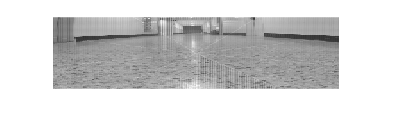


sc1 = permute(reshape(scanData1.data, [480 120]), [2 1]);

imshow(sc1, [0 255])

cameraSub = ros2subscriber(test2, "/camera_pkg/display_mjpeg")

[scanData,status,statustext] = receive(cameraSub,5)

cameraSub1 = ros2subscriber(test2, "/camera_pkg/video_mjpeg")

[scanData1,status1,statustext1] = receive(cameraSub1,5)

sc = permute(reshape(scanData.data, [480 120]), [2 1]);

imshow(sc, [0 255])

image(sc), colormap(gray(256))